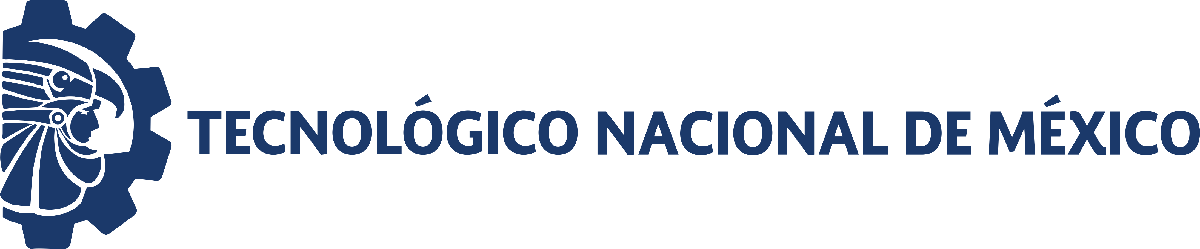                                 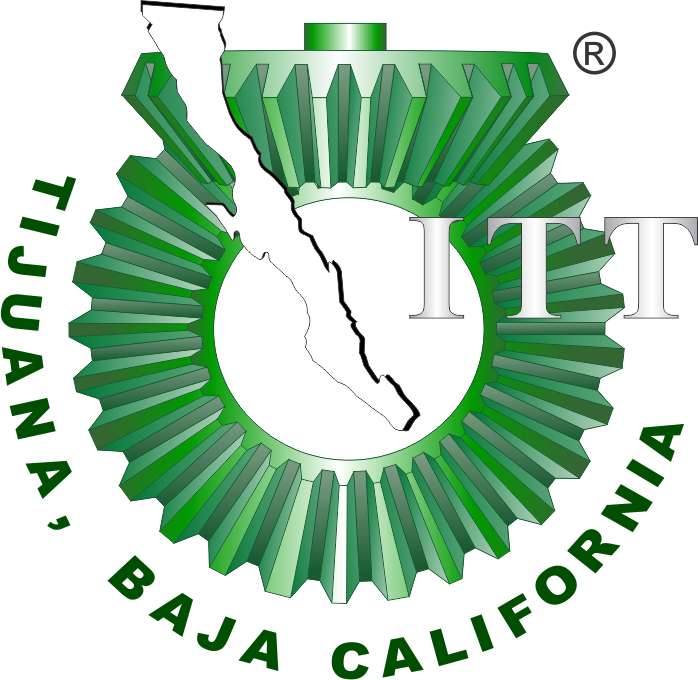

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 3: Liberación controlada de fármacos por hidrogeles

## Información general

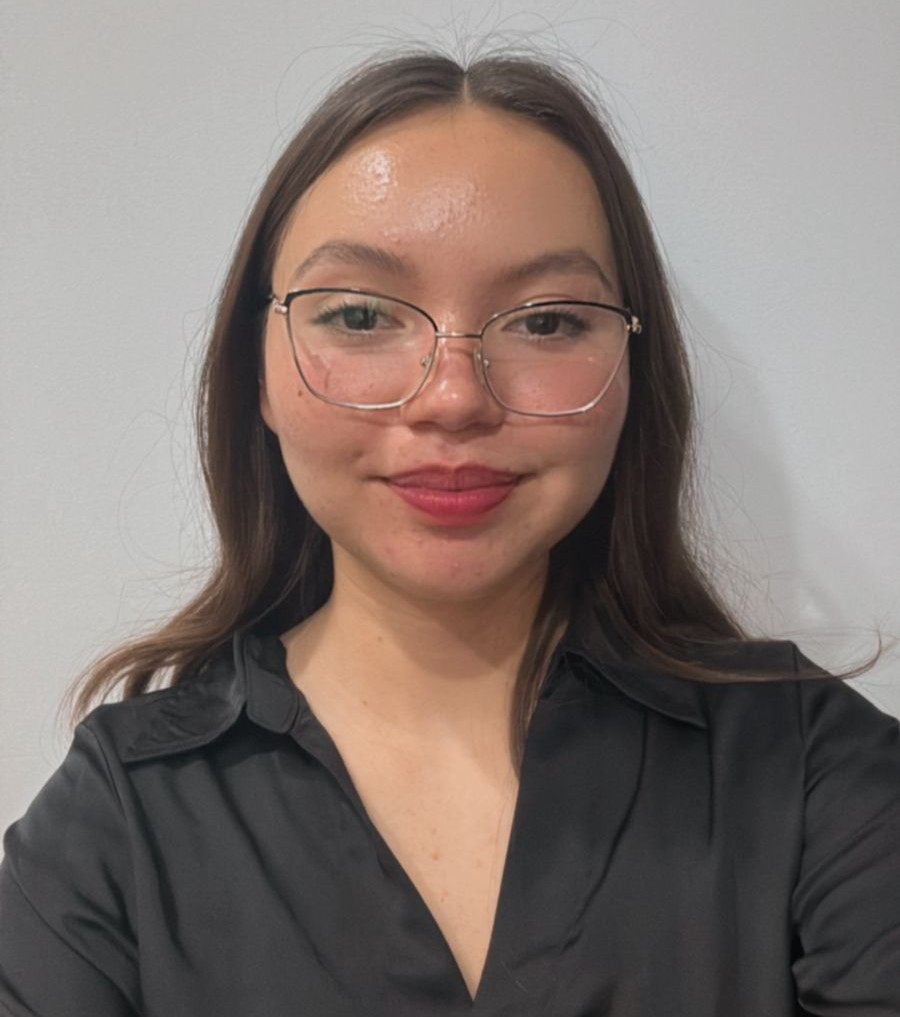

Nombre del alumno: **Karla Emilia Silva Pérez**

Número de control: **22211767**

Correo institucional: **l22211767@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

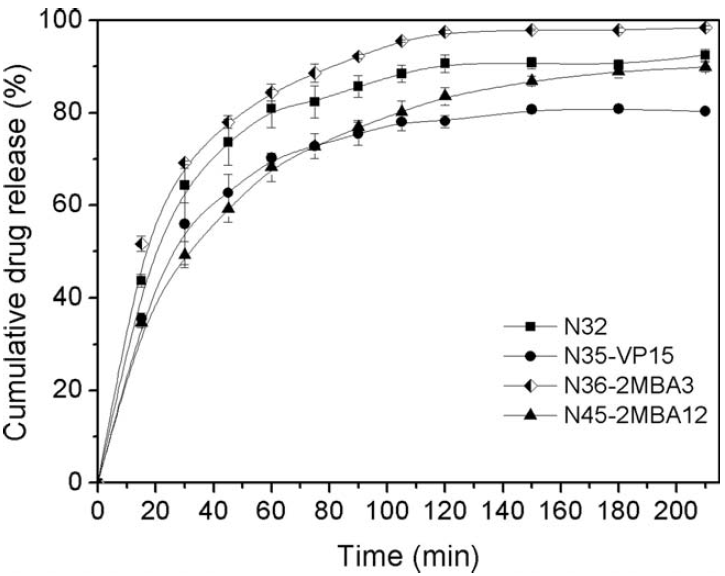

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$x(t) = \rho_1*sqrt(t) - \rho_2*t$ $

Eureqa EDO: $$\dot{x}=\rho_1-\rho_2x$ $

## Datos experimentales

clc; clear; close all; warning('off')
sys = readmatrix('data.csv');
t = round(sys(:,1)); 
x1 = sys(:,2); 
x2 = sys(:,3); 
x3 = sys(:,4); 
x4 = sys(:,5); 

T = table(t,x1,x2,x3,x4);
T.Properties.VariableNames = {'t [min]', 'N45', 'N32', 'N35', 'N36'};
disp(T);

    t [min]     N45       N32       N35       N36  
    _______    ______    ______    ______    ______

        0           0         0         0         0
       15      34.756    44.199    35.628    51.927
       30      49.658    64.569    55.719    69.361
       45      59.462    73.839    62.997    78.082
       60      68.497    81.067    70.461    84.367
       75      72.997    82.403    73.054     88.61
       90      77.061    85.781    76.268    92.224
      105      80.282    88.531     78.16    95.523
      120      83.739    90.731    78.318    97.409
      150      86.981    90.967    80.832    97.923
      180      89.624    90.417    81.189    98.223
      210      90.024    92.617    80.439    98.459



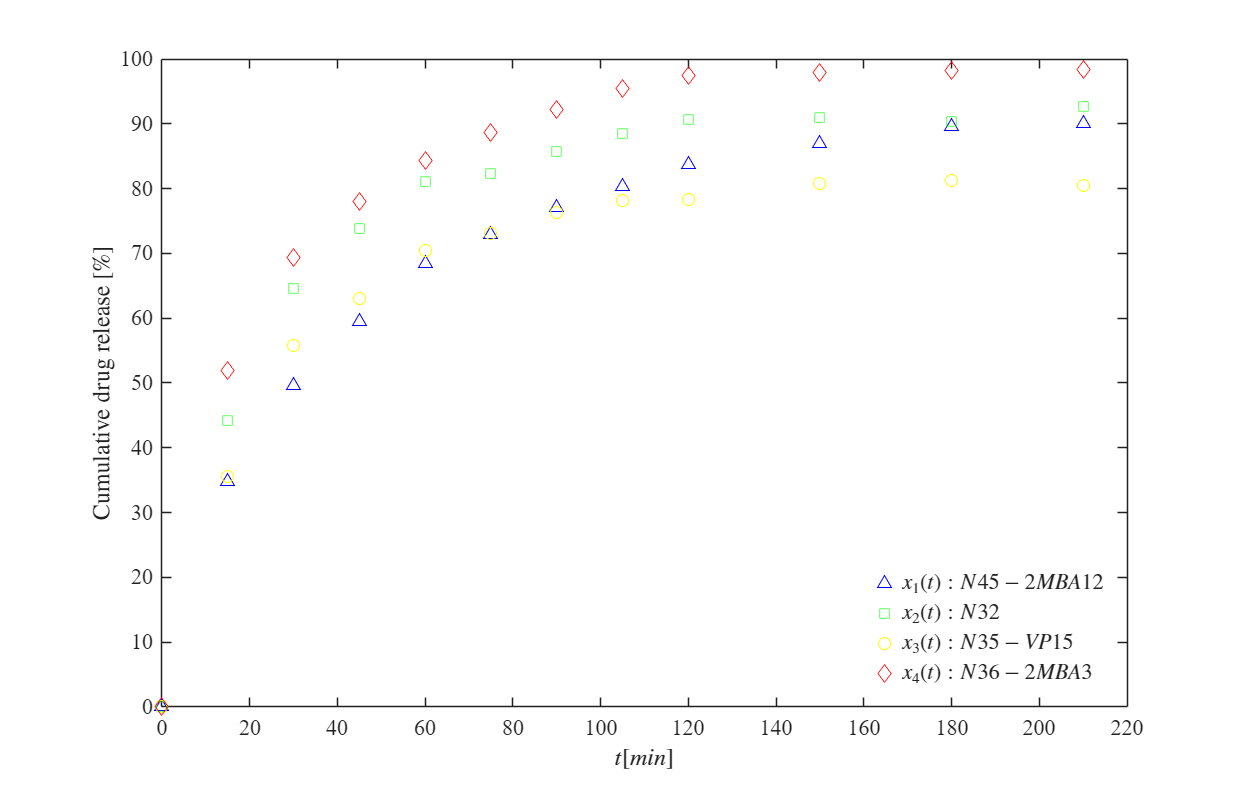

plotsys(t,x1,x2,x3,x4);

## Regresión no lineal, bioestadísticos y experiemntación *in silico*

labels = {'x1(t):N45-2MBA12','x2(t):N32','x3(t):N35-VP15','x4(t):N36-2MBA3'};
xo = [x1,x2,x3,x4]; s = size(xo);

### Función de Pepas

n0 = 0.1; k0 = 0.1;
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[n0;k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        17.821       2.1493      4.7888     13.032      22.61    8.5924e-06
      {'n'}       0.31555     0.025693    0.057248    0.25831     0.3728    2.3482e-07

R-cuadrada ordinaria: 0.98048
Suma residual de cuadrados: 154.4448
Criterio de información de Akaike ajustado (n/k<40): 70.047



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

      {'k'}        30.872       4.2448       9.458    21.414      40.33    2.6855e-05
      {'n'}       0.21753     0.029767    0.066325    0.1512    0.28385    2.5779e-05

R-cuadrada ordinaria: 0.96442
Suma residual de cuadrados: 288.4795
Criterio de información de Akaike ajustado (n/k<40): 77.5445



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate      SE         MoE              CI95             Pvalue  
    __________    ________    _______    ________    __________________    __________

      {'k'}        24.852      3.9052      8.7014     16.151     33.554    8.2049e-05
      {'n'}       0.23583     0.03391    0.075557    0.16027    0.31139    3.9254e-05

R-cuadrada ordinaria: 0.95693
Suma residual de cuadrados: 279.8192
Criterio de información de Akaike ajustado (n/k<40): 77.1787



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        34.427       3.7758       8.413     26.014      42.84    3.6808e-06
      {'n'}        0.2094     0.023778    0.052981    0.15642    0.26238    5.0293e-06

R-cuadrada ordinaria: 0.97634
Suma residual de cuadrados: 214.889
Criterio de información de Akaike ajustado (n/k<40): 74.0104



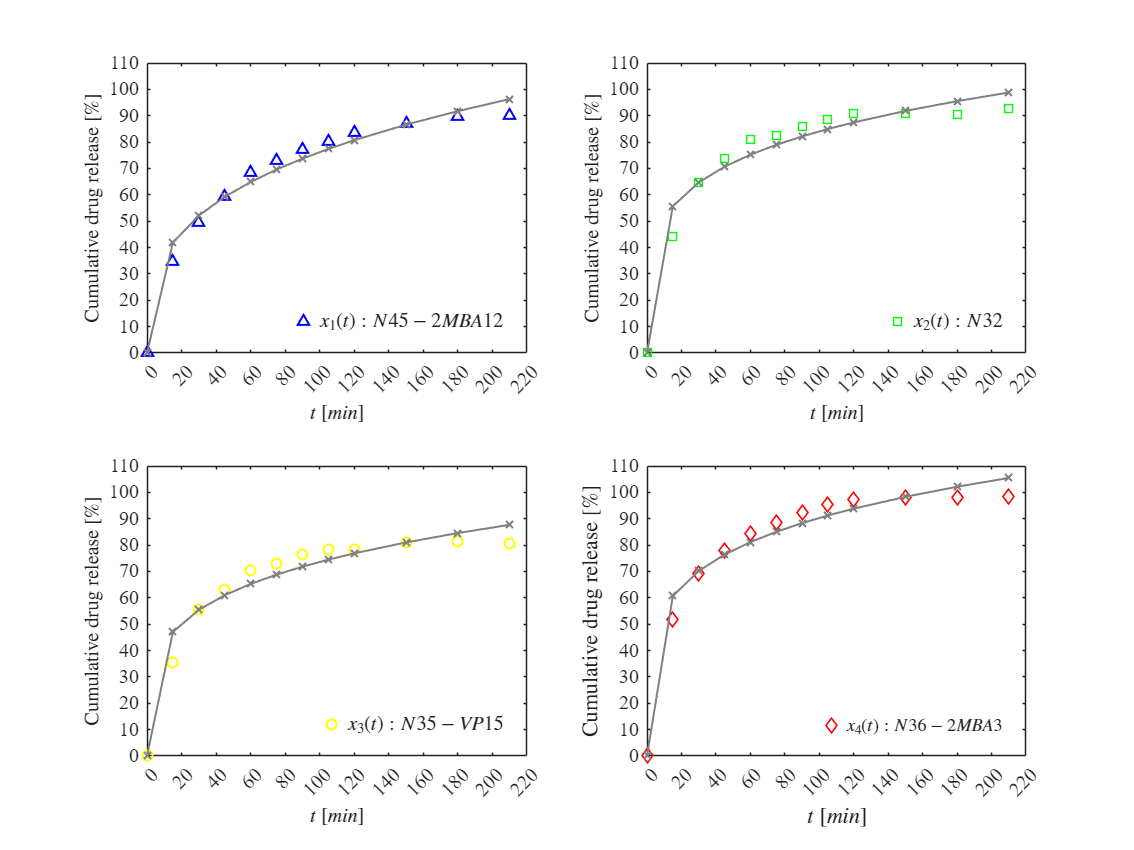

plotresults(t,xo,xp); exportgraphics(gcf,'peppas.pdf','ContentType', 'vector')

### Función farmacocinética de primer orden

beta0 = 100; k0 = 0.01; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl = farmacocinetica(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       87.984       1.5068       3.3574      84.627      91.342    5.2704e-14
     {'k'   }     0.026106    0.0015818    0.0035245    0.022581     0.02963    1.3915e-08

R-cuadrada ordinaria: 0.9905
Suma residual de cuadrados: 75.1971
Criterio de información de Akaike ajustado (n/k<40): 61.4103



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       89.981      0.85081       1.8957      88.086      91.877    1.4001e-16
     {'k'   }     0.040815    0.0018267    0.0040701    0.036745    0.044885    7.2452e-10

R-cuadrada ordinaria: 0.99502
Suma residual de cuadrados: 40.3519
Criterio de información de Akaike ajustado (n/k<40): 53.9407



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       79.813      0.61202       1.3637      78.449      81.177    1.7251e-17
     {'k'   }     0.037268    0.0012758    0.0028427    0.034425    0.040111    5.1575e-11

R-cuadrada ordinaria: 0.99705
Suma residual de cuadrados: 19.1646
Criterio de información de Akaike ajustado (n/k<40): 45.0058



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       96.162       1.3846        3.085      93.077      99.247    9.3338e-15
     {'k'   }     0.042231    0.0029416    0.0065542    0.035677    0.048785    5.3242e-08

R-cuadrada ordinaria: 0.98788
Suma residual de cuadrados: 110.0907
Criterio de información de Akaike ajustado (n/k<40): 65.9846



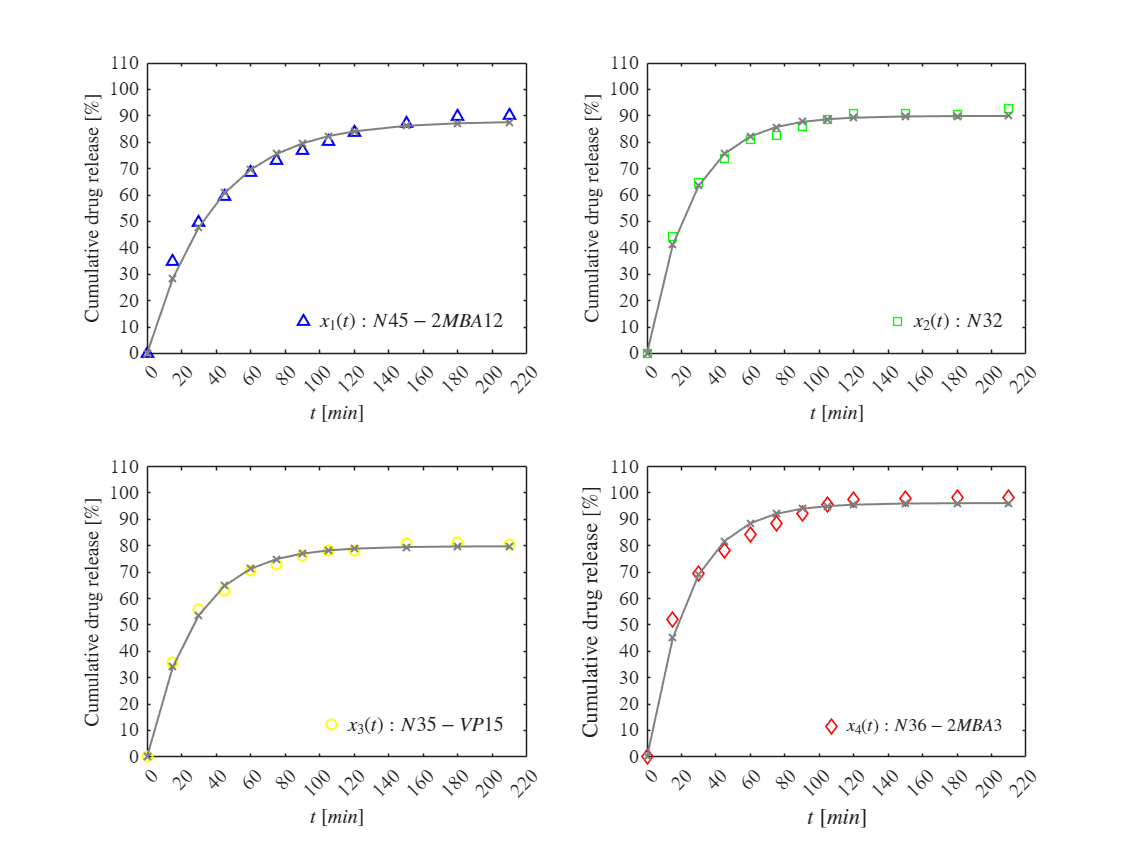

plotresults(t,xo,xfc); exportgraphics(gcf,'farmacocinetica.pdf','ContentType', 'vector')

### Eureqa: Función en el tiempo

rho1_0 = 11.57; rho2_0 = 0.36; xe = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl_eureqa = eureqafunction(t,xo(:,i),[rho1_0;rho2_0]);
    xe(:,i) = mdl_eureqa.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

     {'rho1'}      11.239      0.21978      0.4897      10.75     11.729    1.9769e-13
     {'rho2'}     0.33889     0.018974    0.042278    0.29661    0.38117    6.4682e-09

R-cuadrada ordinaria: 0.99655
Suma residual de cuadrados: 27.2888
Criterio de información de Akaike ajustado (n/k<40): 49.2467



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

     {'rho1'}      14.613      0.25961     0.57844     14.034     15.191     7.598e-14
     {'rho2'}     0.57773     0.022413    0.049938    0.52779    0.62767    1.7743e-10

R-cuadrada ordinaria: 0.9953
Suma residual de cuadrados: 38.074
Criterio de información de Akaike ajustado (n/k<40): 53.2434



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate      SE         MoE              CI95             Pvalue  
    __________    ________    _______    ________    __________________    __________

     {'rho1'}      12.543     0.27544     0.61372     11.929     13.157    6.2778e-13
     {'rho2'}     0.48242     0.02378    0.052985    0.42944     0.5354     1.867e-09

R-cuadrada ordinaria: 0.9934
Suma residual de cuadrados: 42.861
Criterio de información de Akaike ajustado (n/k<40): 54.6645



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

     {'rho1'}      15.748      0.13004     0.28975     15.458     16.038    3.6163e-17
     {'rho2'}      0.6255     0.011227    0.025015    0.60049    0.65052    8.4132e-14

R-cuadrada ordinaria: 0.99895
Suma residual de cuadrados: 9.5533
Criterio de información de Akaike ajustado (n/k<40): 36.6516



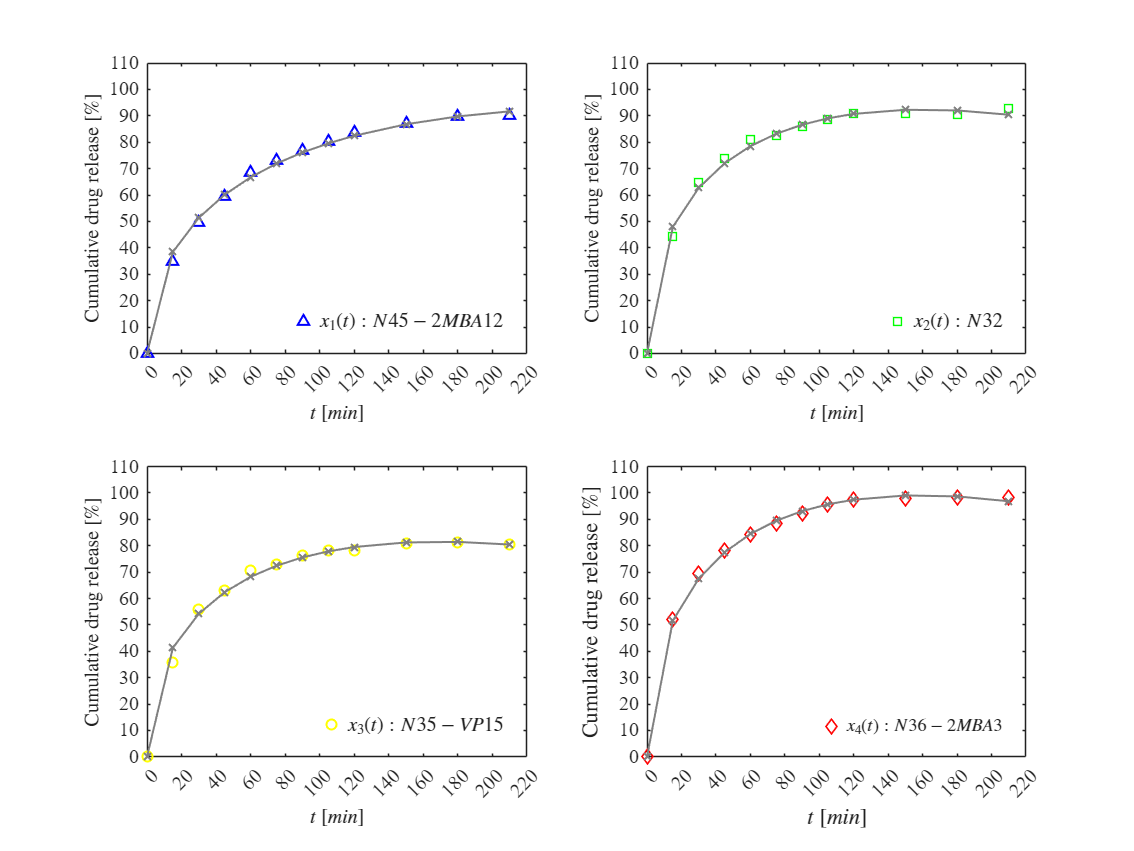

plotresults(t,xo,xe); exportgraphics(gcf,'eureqa.pdf','ContentType', 'vector')

### Eureqa: Farmacocinética de primer orden

rho1_0 = 2.32; rho2_0 = 0.0263; xe2 = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel: ', string(labels(i))]);
    mdl_eureqa = eureqafunction2(t,xo(:,i),[rho1_0;rho2_0]);
    xe2(:,i) = mdl_eureqa.Fitted; disp(' ');
end

    "Resultados para el Hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       2.2969      0.11233      0.25029      2.0466      2.5472    1.7285e-09
     {'rho2'}     0.026106    0.0015819    0.0035246    0.022581     0.02963    1.3919e-08

R-cuadrada ordinaria: 0.9905
Suma residual de cuadrados: 75.1971
Criterio de información de Akaike ajustado (n/k<40): 61.4103



    "Resultados para el Hidrogel: "    "x2(t):N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       3.6726       0.1454      0.32398      3.3486      3.9966    2.1686e-10
     {'rho2'}     0.040815    0.0018267    0.0040702    0.036745    0.044885    7.2462e-10

R-cuadrada ordinaria: 0.99502
Suma residual de cuadrados: 40.3519
Criterio de información de Akaike ajustado (n/k<40): 53.9407



    "Resultados para el Hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       2.9745     0.088744      0.19773      2.7767      3.1722    1.3205e-11
     {'rho2'}     0.037268    0.0012758    0.0028427    0.034425    0.040111    5.1579e-11

R-cuadrada ordinaria: 0.99705
Suma residual de cuadrados: 19.1646
Criterio de información de Akaike ajustado (n/k<40): 45.0058



    "Resultados para el Hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Grados de libertad: 10
Valor t-student: 2.2281
Alpha: 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}        4.061      0.25153      0.56045      3.5006      4.6215    1.7208e-08
     {'rho2'}     0.042231    0.0029416    0.0065543    0.035677    0.048785    5.3249e-08

R-cuadrada ordinaria: 0.98788
Suma residual de cuadrados: 110.0907
Criterio de información de Akaike ajustado (n/k<40): 65.9846



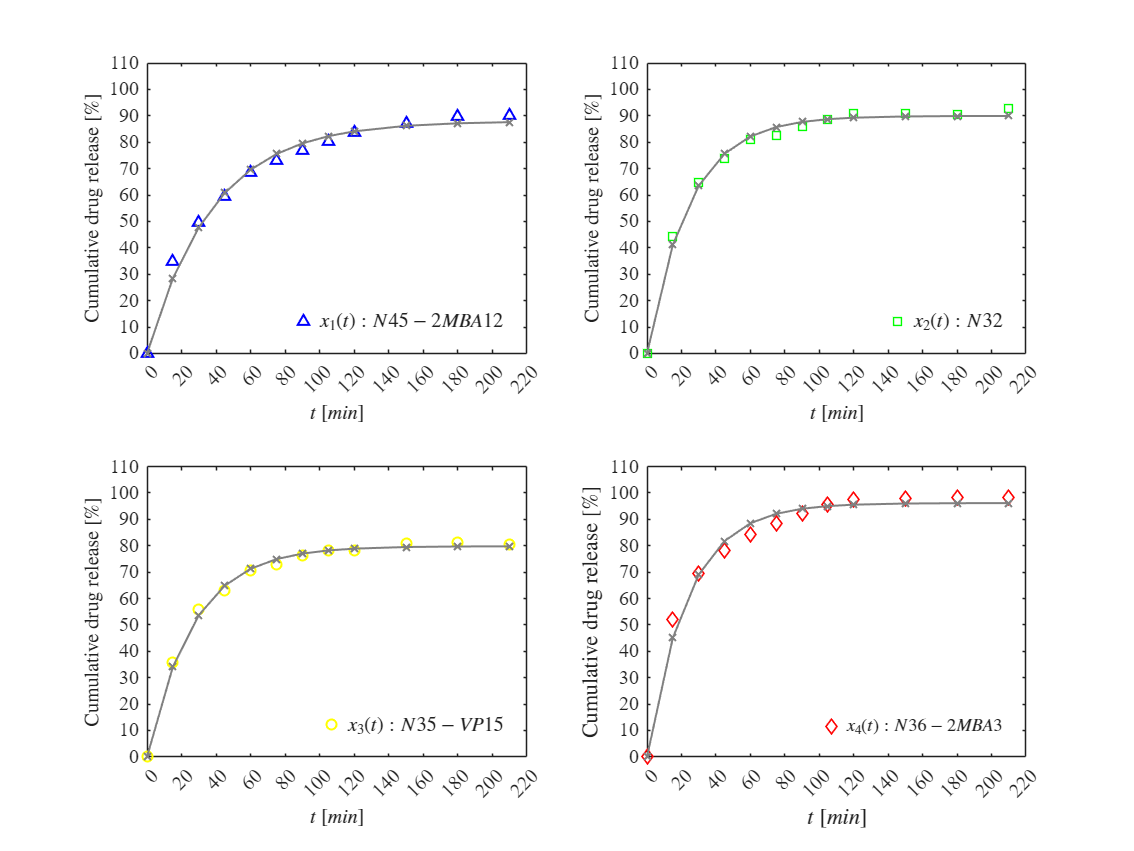

plotresults(t,xo,xe2); exportgraphics(gcf,'eureqaODE.pdf','ContentType', 'vector')

## Funciones

function plotsys(t,x1,x2,x3,x4)
    figure('Color','w','Units','centimeters','Position',[2 2 22 14])
    FS = 11;
    MS = 6;
    hold on; box on;
    plot(t,x1,'^-','Color','b','LineStyle','none','MarkerSize',MS)
    plot(t,x2,'s-','Color','g','LineStyle','none','MarkerSize',MS)
    plot(t,x3,'o-','Color','y','LineStyle','none','MarkerSize',MS)
    plot(t,x4,'d-','Color','r','LineStyle','none','MarkerSize',MS)
    xlim([0 220])
    ylim([0 100])
    xlabel('$t [min]$','Interpreter','Latex','FontSize',FS)
    ylabel('Cumulative drug release [\%]','Interpreter','Latex','FontSize',FS)
    L = legend('$x_1(t): N45-2MBA12$','$x_2(t): N32$','$x_3(t): N35-VP15$','$x_4(t): N36-2MBA3$');
    set(L,'Interpreter','Latex','FontSize',FS,'Box','Off','Location','SouthEast');
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'data.pdf','ContentType', 'vector')
end

function plotresults(t,xo,xp)
    set(figure(), 'color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,15])

    subplot(2,2,1)
    hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t,xo(:,1), '^-', 'LineWidth', 1, 'MarkerSize', 5, 'Color', 'b', 'LineStyle', 'none')
    plot(t,xp(:,1), '-x', 'LineWidth', 1, 'MarkerSize', 5,'Color', [0.5, 0.5, 0.5])
    xlabel('$t$ $[min]$', 'Interpreter', 'Latex')
    ylabel('Cumulative drug release $[\%]$', 'Interpreter', 'Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_1(t): N45-2MBA12$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');
    
    subplot(2,2,2)
    hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t,xo(:,2), 's-', 'LineWidth', 1, 'MarkerSize', 5, 'Color', 'g', 'LineStyle', 'none')
    plot(t,xp(:,2), '-x', 'LineWidth', 1, 'MarkerSize', 5,'Color', [0.5, 0.5, 0.5])
    xlabel('$t$ $[min]$', 'Interpreter', 'Latex')
    ylabel('Cumulative drug release $[\%]$', 'Interpreter', 'Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_2(t): N32$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');
    
    subplot(2,2,3)
    hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t,xo(:,3), 'o-', 'LineWidth', 1, 'MarkerSize', 5, 'Color', 'y', 'LineStyle', 'none')
    plot(t,xp(:,3), '-x', 'LineWidth', 1, 'MarkerSize', 5,'Color', [0.5, 0.5, 0.5])
    xlabel('$t$ $[min]$', 'Interpreter', 'Latex')
    ylabel('Cumulative drug release $[\%]$', 'Interpreter', 'Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_3(t): N35-VP15$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');

    subplot(2,2,4)
    hold on; box on; grid off; fontsize(10,"points"); set(gca, 'FontName', 'Times New Roman')
    plot(t,xo(:,4), 'd-', 'LineWidth', 1, 'MarkerSize', 5, 'Color', 'r', 'LineStyle', 'none')
    plot(t,xp(:,4), '-x', 'LineWidth', 1, 'MarkerSize', 5,'Color', [0.5, 0.5, 0.5])
    xlabel('$t$ $[min]$', 'Interpreter', 'Latex')
    ylabel('Cumulative drug release $[\%]$', 'Interpreter', 'Latex')
    xlim([0 220]); xticks(0:20:220)
    ylim([0 110]); yticks(0:10:110)
    L = legend('$x_4(t): N36-2MBA3$');
    set(L,'Interpreter','Latex','Box','Off','Location','SouthEast');
    
end

## Modelos matemáticos y bioestadísticos

function biostats(mdl, Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2, dof);
    MoE = SE * tval;
    n_datos = mdl.NumObservations;
    k_params = mdl.NumCoefficients; 
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    disp(['Cantidad de datos: ', num2str(n_datos)])
    disp(['Cantidad de parámetros: ', num2str(k_params)])
    disp(['Grados de libertad: ', num2str(dof)])
    disp(['Valor t-student: ', num2str(tval)])
    disp(['Alpha: ', num2str(alpha)])
    disp(' '); disp(Results)
    R2o = mdl.Rsquared.Ordinary;
    SSE = mdl.SSE;
    AICc = mdl.ModelCriterion.AICc;
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);
    fprintf(['\nCriterio de información de Akaike ajustado (n/k<40): ', num2str(AICc), '\n\n']);
end 

function mdl = peppas(to,xo,par)

    function x = model(par,t)
        k = par(1); n = par(2);
        x = k*t.^n;
    end
    
    mdl = fitnlm(to,xo,@model,par);
    Parameters = {'k'; 'n'};
    biostats(mdl,Parameters)
end

function mdl = farmacocinetica(to,xo,par)

    function x = model(par, t)
        beta = par(1); 
        k = par(2);
        x = beta * (1 - exp(-k * t));
    end

    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'beta'; 'k'};
    biostats(mdl, Parameters)
end

function mdl = eureqafunction(to,xo,par)

    function x = model(par, t)
        rho1 = par(1); rho2 = par(2);
        x = rho1*sqrt(t)-rho2*t;
    end

    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'rho1'; 'rho2'};
    biostats(mdl, Parameters)
end

function mdl = eureqafunction2(to, xo, par)

    function xi = model(par, ta)
            rho1 = par(1); 
            rho2 = par(2);
            dt = 1E-1; 
            time = (0:dt:max(ta))';
            x = zeros(length(time),1); 
            x(1) = 0; 
            
            f = @(x_val) rho1 - rho2 * x_val;
    
            % Runge-Kutta
            for i = 1:(length(time) - 1) 
                k1 = f(x(i));
                k2 = f(x(i) + (dt/2)*k1);
                k3 = f(x(i) + (dt/2)*k2);
                k4 = f(x(i) + dt*k3);
                
                x(i+1) = x(i) + (dt/6) * (k1 + 2*k2 + 2*k3 + k4);
            end
            
            xi = interp1(time, x, ta, 'linear', 'extrap');
    end
    
    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'rho1'; 'rho2'};
    biostats(mdl, Parameters);
end